% Define links
%        theta  d  a  alpha
L1 = Link([0    15 0   -pi/2], 'standard');
L2 = Link([0    0 20   0], 'standard');
L3 = Link([0    0 25   0], 'standard');
%join links
dobot = SerialLink([L1 L2 L3],'name','MyRobot');
dobot

 
dobot = 
 
MyRobot:: 3 axis, RRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         15|          0|    -1.5708|          0|
|  2|         q2|          0|         20|          0|          0|
|  3|         q3|          0|         25|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


or_tr = load("trajectory_mnist_test.mat");
trajectories = or_tr.predicted_tr

trajectories = trajectories(:,:,1) =

   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015   32.3015  

digit = 0

digit = 0

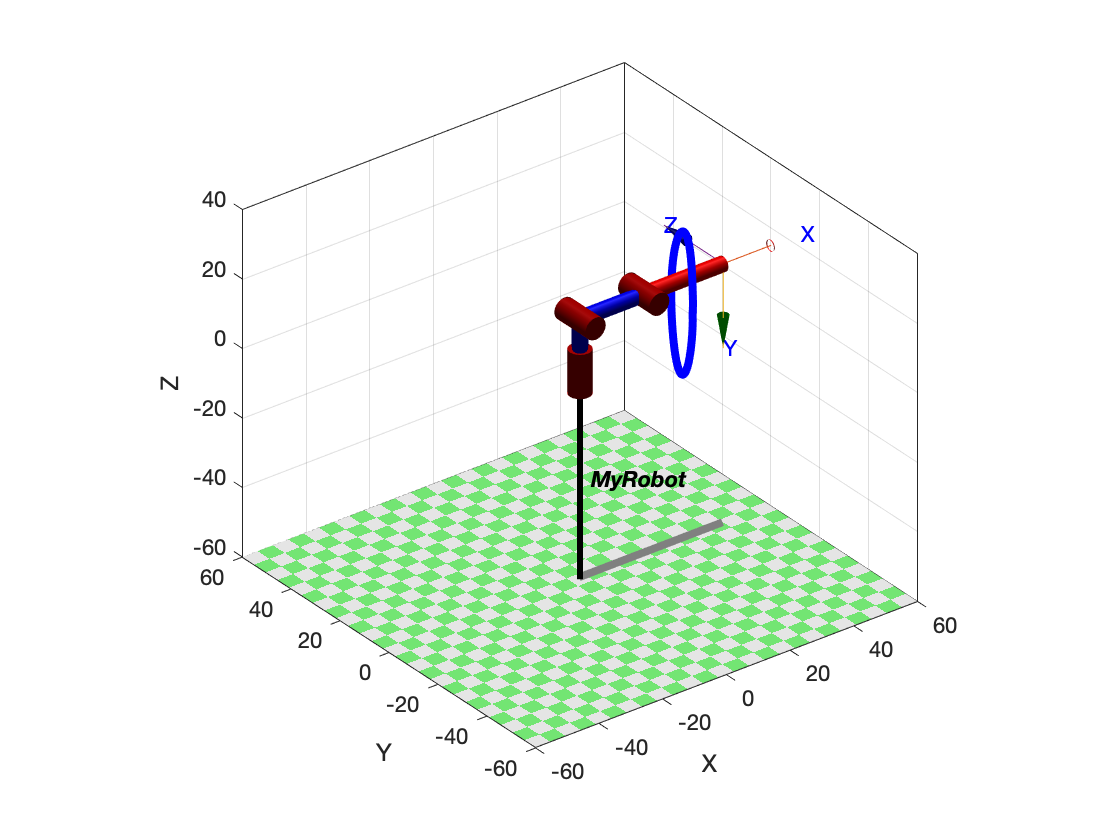

image_name = 'digit-0.gif';
figure(1)
C = trajectories(digit+1, :, :);
d = reshape(C, [301,3]);
points = d';
plot3(points(1,:),points(2,:),points(3,:),'-b','LineWidth',4);
hold on;
dobot.plot([0 0 0], 'trail', '-r');% show init robot 
hold off;
box on;

Animate: saving video --> digit-0.gif with profile 'GIF'


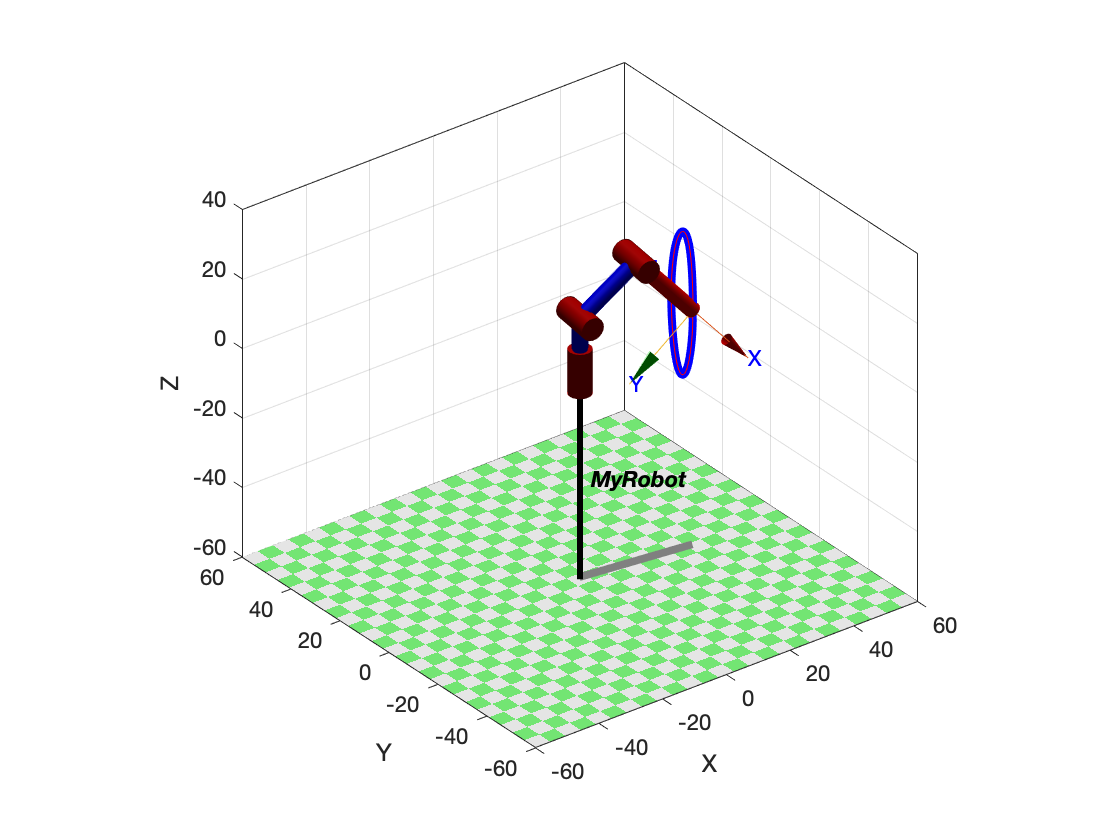

%pionts tranform
points_t = points';
T = transl(points_t);
T_0 = transl(points_t(1,:));
T_1 = transl(points_t(301,:));

Q_0 = dobot.ikine(T_0,'mask',[1 1 1 0 0 0]);
Q_1 = dobot.ikine(T_1,'mask',[1 1 1 0 0 0]);
% mask vector
% do inverse kinematics
q = dobot.ikine(T,[0 0 0],'mask',[1 1 1 0 0 0]);

figure(3);
plot3(points(1,:),points(2,:),points(3,:),'-b','LineWidth',4);
box on;
opt = RTBPlot.plot_options(dobot, {'trail','*r'});
% dobot.plot(q);
% dobot.plot(q,'trail','.b','tile1color',[0 255 255],'tile2color',[255 251 0]);
% dobot.plot(q,'trail',{'.r', 'LineWidth', 2}, 'notiles','tilesize',300, 'movie', 'demo1.gif');
dobot.plot(q, 'trail', '.r','movie', image_name);

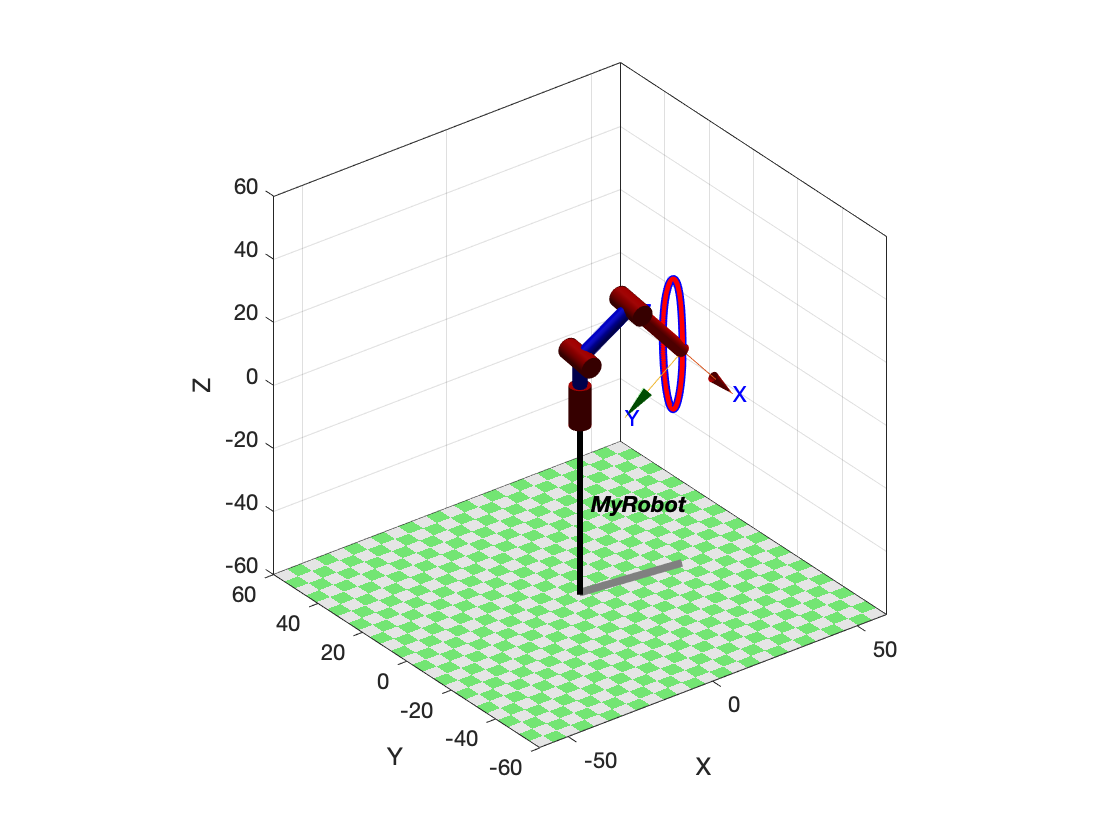

box on;

step = 60

step = 60

q1 = Q_0;
q2 = Q_1;
[q_m, v_m, a_m] = jtraj(q1, q2, step);

%Top 1/2 Time, movement, joint shortening
q11 = Q_0;
q12 = q(step/2,:);
[q_1, v_1, a_1] = jtraj(q11, q12, step/2);

%Last 1/2 Time, movement, joint elongation
q21 = q(step/2,:);
q22 = Q_1;
[q_2, v_2, a_2] = jtraj(q21, q22, step/2);

%The original L3 The stationary trajectory is replaced by two segments L3 Trajectory after merging motion trajectory
q_m(:, 3) = [q_1(:,3);q_2(:, 3)];%Track merging for moving joints
v_m(:, 3) = [v_1(:,3);v_2(:, 3)];%Speed fusion for moving joints
a_m(:, 3) = [a_1(:,3);a_2(:, 3)];%Acceleration fusion for moving joints
%q_m, v_m, a_m Is the final triaxial displacement, velocity, acceleration

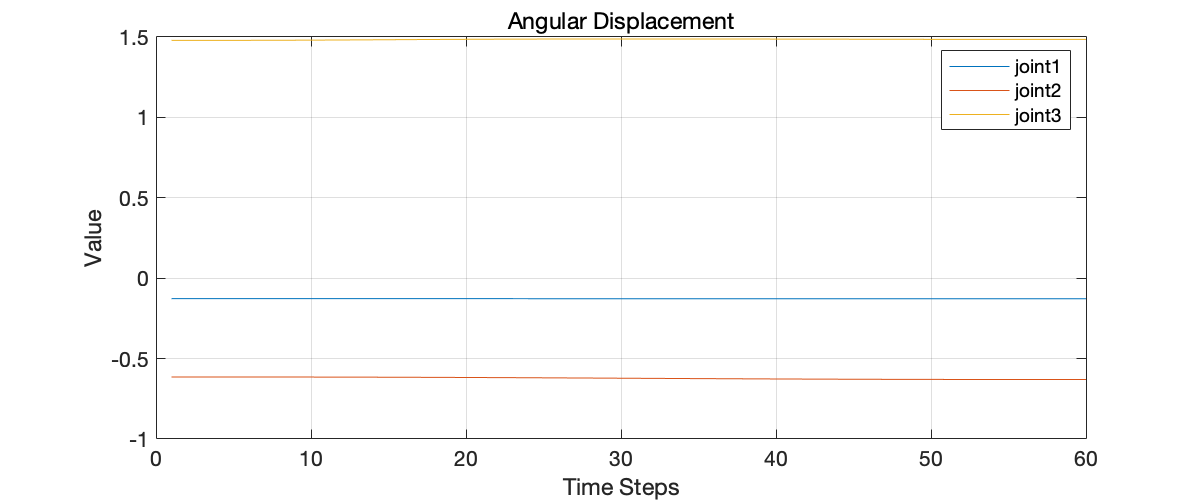

%The curves of displacement, velocity and acceleration are displayed
f5 = figure(5); 
f5.Position = [100 100 600 250];
plot(1:step, q_m);
legend('joint1', 'joint2', 'joint3');
legend('show', 'Location',"best");
% yline(0,'--')
% legend('off')
title('Angular Displacement');
xlabel('Time Steps');
ylabel('Value');
grid on;

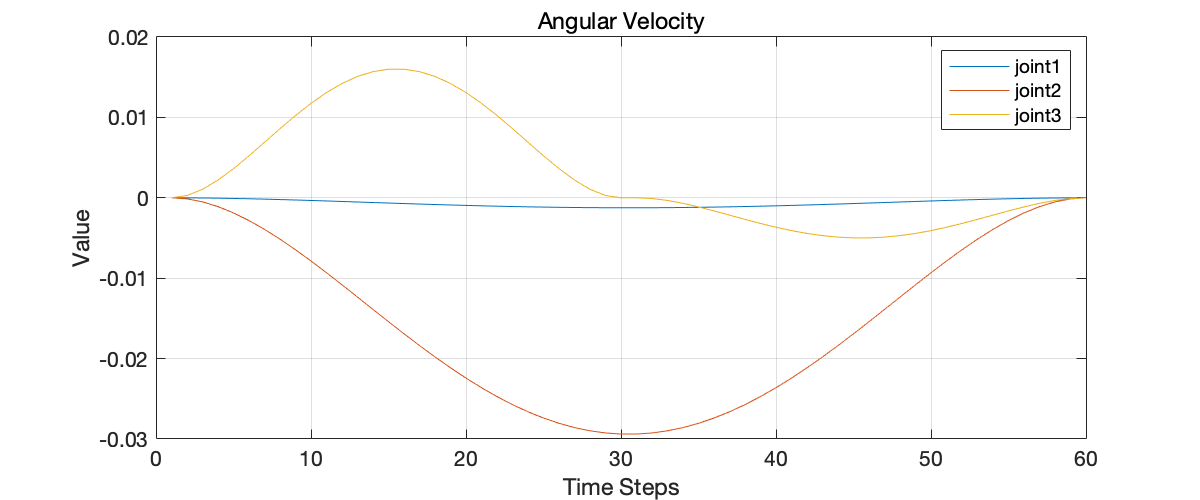

f6 = figure(6);
f6.Position = [100 100 600 250];
plot(1:step, v_m);
legend('joint1', 'joint2', 'joint3');
legend('show', "Location","best");
title('Angular Velocity');
xlabel('Time Steps');
ylabel('Value');
grid on;

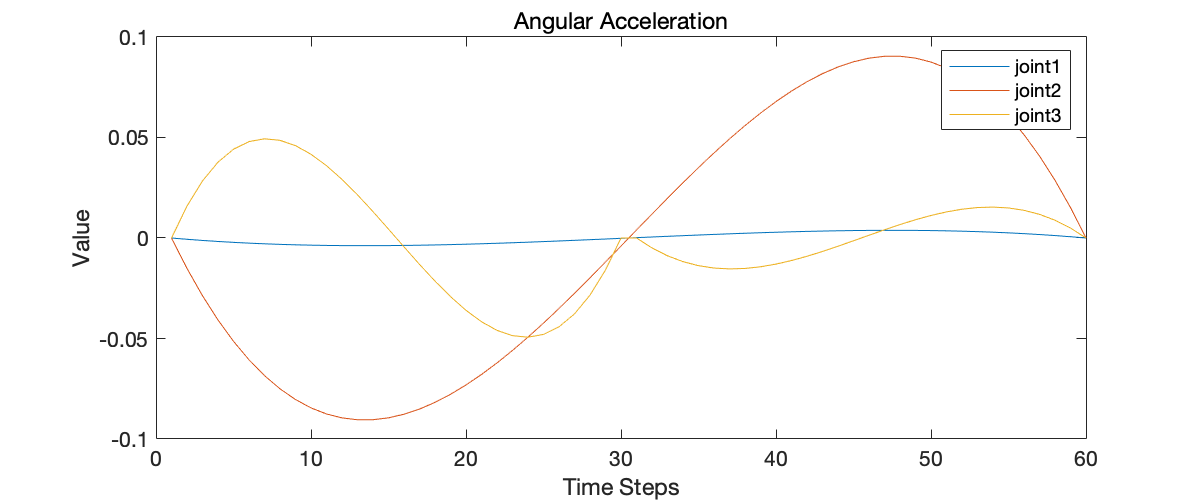

f7 = figure(7);
f7.Position = [100 100 600 250];
plot(1:step, a_m);
legend('joint1', 'joint2', 'joint3');
legend('show', "Location","best");
title('Angular Acceleration');
xlabel('Time Steps');
ylabel('Value');

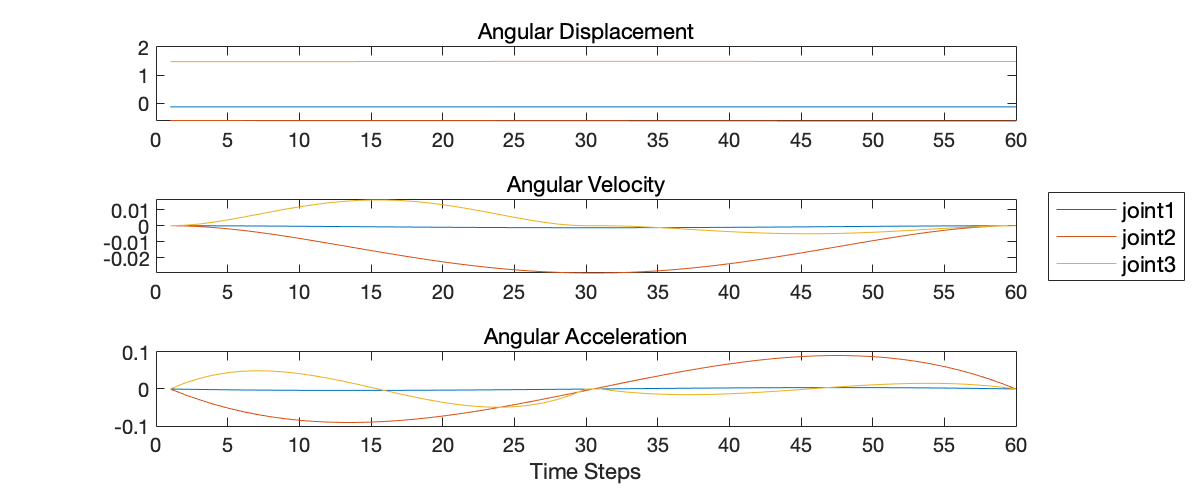

% Create plots
t = tiledlayout(3,1); % Requires R2019b or later
nexttile;
plot(1:step, q_m);
title('Angular Displacement');
xticks(0:5:step)
% yticks(-4:0.5:4)

nexttile;
plot(1:step, v_m);
title('Angular Velocity');
xticks(0:5:step)
% yticks(-6:1:6)

nexttile;
plot(1:step, a_m);
title('Angular Acceleration');
xticks(0:5:step)
% yticks(-20:5:20)


xlabel('Time Steps');
legend({'joint1', 'joint2', 'joint3'}, "Location","best");
lgd = legend;
lgd.Layout.Tile = 'east';
lgd.FontSize = 11;


% Add shared title and axis labels
% title(t,'My Title')
% xlabel(t,'x-values')
% ylabel(t,'y-values')
% t.TileSpacing = 'compact';

% Move plots closer together